**Plotting data at the channel and source level**

***Introduction***

To visualize your data you can use FieldTrip's high-level plotting functions, which are optimised for the FT data structures. Like other high-level functions they take a cfg as first input argument, followed by the data. These functions take care of all bookkeeping and some of the functions allow you to interact with the data by clicking in the figure.

Alternatively, you can use the low-level FieldTrip plotting functions. These are located in the plotting sub-directory and are named ft_plot_xxx. You can find them by typing in the command window “help ft_plot_” and then press the Tab key.

Of course you can use the standard MATLAB functions ('plot, 'image', 'images', 'patch').

***Background***

The goal of the plotting functions in FieldTrip is to ease the visualization of complex data structures with multiple dimensions and with data that is not trivial to interpret spatially. This is accomplished with high-level functions (e.g. ft_topoplotER or ft_multiplotTFR) and low-level functions (with prefixes 'ft_plot_' and 'ft_select_', e.g. ft_plot_matrix or ft_select_box). For more simple data, such as a set of reaction times of the subject, we expect you to use the standard MATLAB plotting functions.

The high-level functions take care of the data bookkeeping and call the low-level function. If you want to make more complex figures or tweak all options, you can bypass the high-level functions and call the low-level functions instead. This is especially useful if there is no data selection and bookkeeping involved, e.g. when you want to plot multiple geometrical objects (like sensors, source model, head surface, etc).

To determine which high-level functions are suitable for you depends on the type of data you have: sensor or source space data. In this tutorial we assume that you already have the data from the event related averaging tutorial, the time-frequency representations of power tutorial and the applying beamforming techniques in the frequency domain tutorial, and we will demonstrate plotting at both the sensor and source level.

Let us start by loading some data.

% cd dccnpath('/home/common/matlab/fieldtrip/data/ftp/tutorial/plotting')
cd '/Volumes/128GB/Google Drive/data_visualization_DS/Electrophys - data for hands-on/'

load avgFC.mat
load GA_FC.mat
load TFRhann.mat
load statERF.mat
load statTFR.mat
load sourceDiff.mat


***Plotting data at the channel level***

Data at the channel level has a value for each sensor (MEG) or electrode (EEG). Those values can change over time and/or over frequency. 

**Singleplot functions**

With ft_singleplotER you can make a plot using the avgFC data from the ERF tutorial by the following code:

The ft_singleplotER function first selects the data to be plotted, in this case channel MLC24, from -0.2 to 1.0 seconds. Subsequently this selected data is plotted with the MATLAB plot function. 

the call to "ft_singleplotER" took 2 seconds and required the additional allocation of an estimated 2 MB


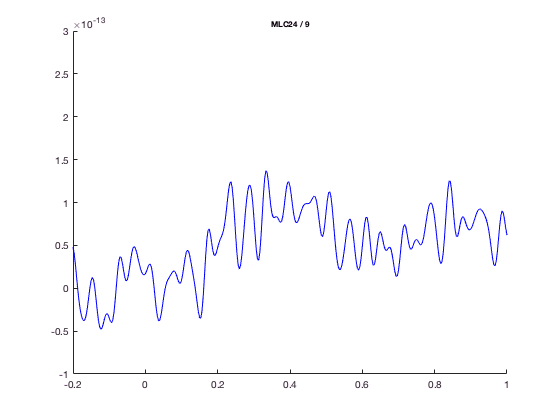

cfg = [];
cfg.xlim = [-0.2 1.0];
cfg.ylim = [-1e-13 3e-13];
cfg.channel = 'MLC24';
figure; ft_singleplotER(cfg,avgFC);

You could make the same plot by the following code:

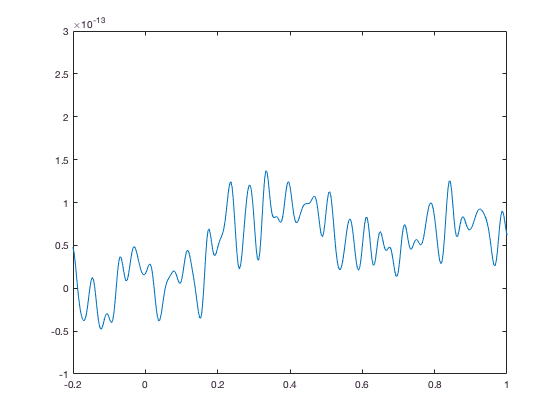

selected_data = avgFC.avg(9,241:601); % MLC24 is the 9th channel, -0.2 to 1.0 is sample 241 to 601
selected_time = avgFC.time(241:601);
figure;
plot(selected_time, selected_data)
xlim([-0.2 1.0])
ylim([-1e-13 3e-13])

The advantage of ft_singleplotER is that it does the bookeeping for you. E.g. you can plot the mean over all MLC channels, which are MEG channels over left-central regions:

the call to "ft_singleplotER" took 1 seconds and required the additional allocation of an estimated 2 MB


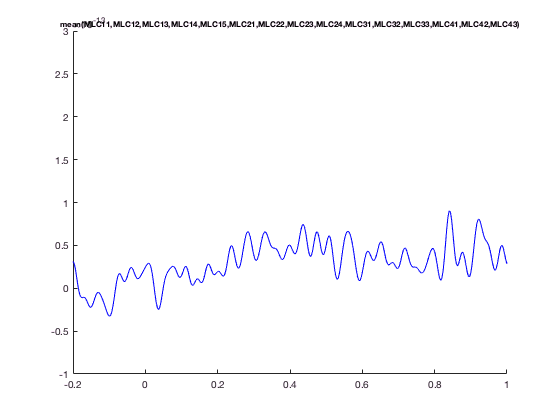


cfg = [];
cfg.xlim = [-0.2 1.0];
cfg.ylim = [-1e-13 3e-13];
cfg.channel = 'MLC*';
figure; ft_singleplotER(cfg,avgFC);

and change the line width or color:

the call to "ft_singleplotER" took 0 seconds and required the additional allocation of an estimated 1 MB


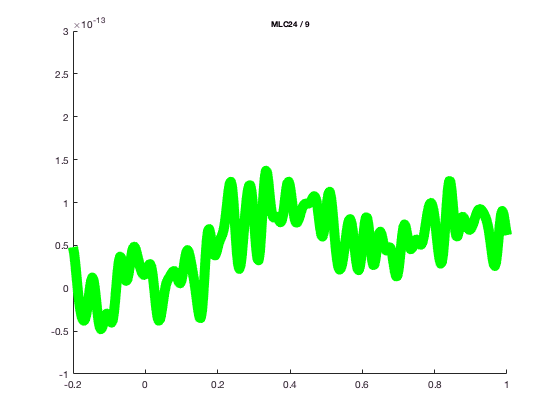

cfg = [];
cfg.xlim = [-0.2 1.0];
cfg.ylim = [-1e-13 3e-13];
cfg.channel = 'MLC24';
cfg.linewidth = 10;
cfg.graphcolor = 'g';
figure; ft_singleplotER(cfg,avgFC);

The ft_singleplotER function might not look so impressive compared to standard plot; that is because the ERF data representation is quite simple.

The advantage of using the standard MATLAB plot function is that you can easily find all documentation for it ("doc plot") and tweak the low level figure characteristics.

The FieldTrip plotting functions have a lot of built-in intelligence to make plotting of multidimensional data easier. It is for instance possible to do baseline correction before plotting, by specifying the baseline type and time limits. In the plotting functions either the FieldTrip function ft_timelockbaseline or ft_freqbaseline is called. If you specify multiple channels in cfg.channel both singleplot functions will plot the mean over these channels. In the plotting functions the FieldTrip function ft_channelselection is called, which makes it straightforward to plot for instance the mean TFR (download here, see time-frequency analysis tutorial)of the left central channels.

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_singleplotTFR" took 3 seconds and required the additional allocation of an estimated 11 MB


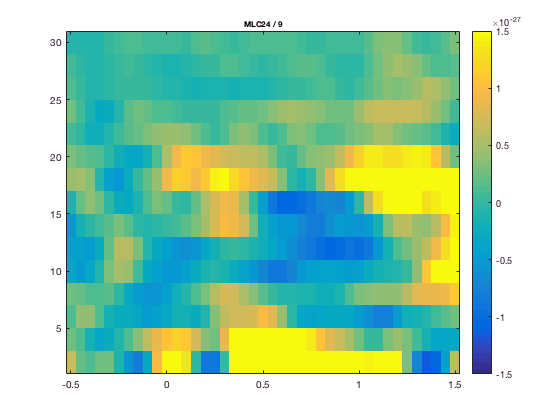

cfg = [];
cfg.baseline = [-0.5 -0.1]; 
cfg.baselinetype = 'absolute'; 	
cfg.zlim = [-1.5e-27 1.5e-27];	
cfg.channel = 'MLC24'; % top figure
figure; ft_singleplotTFR(cfg, TFRhann);

or wiht the average over a group of channels:

cfg.channel  = 'MLC*' % bottom figure

cfg =         baseline: [-0.5000 -0.1000]
    baselinetype: 'absolute'
            zlim: [-1.5000e-27 1.5000e-27]
         channel: 'MLC*'


the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_singleplotTFR" took 1 seconds and required the additional allocation of an estimated 4 MB


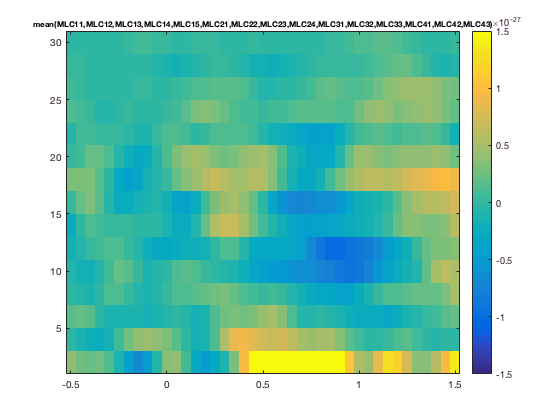

figure; ft_singleplotTFR(cfg,TFRhann);

You can again make very similar figures using standard MATLAB plotting functions.

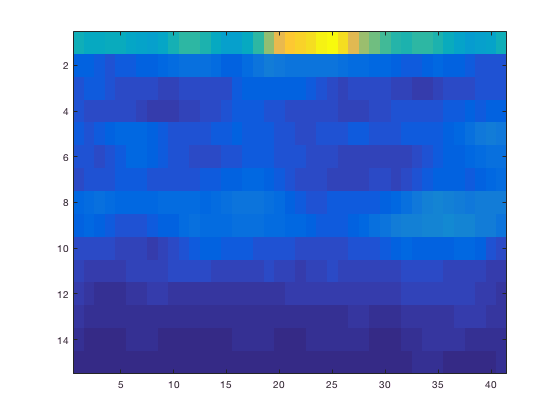

chanindx = find(strcmp(TFRhann.label, 'MLC24'));
figure; imagesc(squeeze(TFRhann.powspctrm(chanindx,:,:)));

The default MATLAB image is shown upside down compared to usual MEG/EEG conventions. Along the axes you can see the number of time and frequency bins, but not the acqual time and frequency. This can be fixed of course.

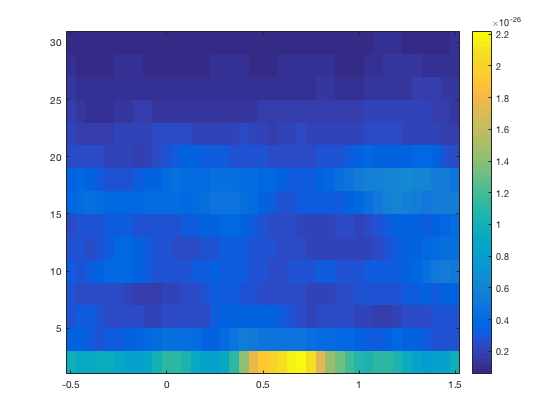

figure; imagesc(TFRhann.time, TFRhann. freq, squeeze(TFRhann.powspctrm(chanindx,:,:)));
axis xy % flip vertically
colorbar

Still, the power is more difficult to interpret due to it being larger for low frequencies and smaller for high frequencies. This 1/f characteristic is removed from the figure by baseline correction. See also ft_freqbaseline.

**Multiplot functions**

The multiplot functions work similarly to the singleplot functions, again first by selecting the data and subsequently using the MATLAB functions plot and imagesc. But instead of one plot, multiple plots are made; one for each channel. These plots are arranged according to a specified layout in one pair of axes. In the subsequent figures you can see these axes that are normally set to “off”. 

cfg = [];
cfg.layout = 'CTF151.lay';
figure; ft_multiplotER(cfg, avgFC);

the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 1 MB
reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_multiplotER" took 7 seconds and required the additional allocation of an estimated 26 MB


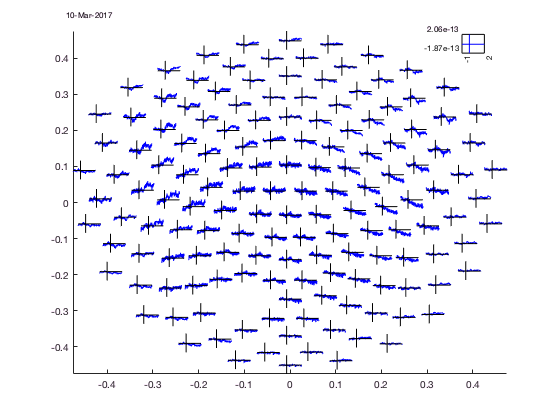

axis on % this shows the actual MATLAB axes

Normally the axes of the figure are not visible, only the “axis” of each channel, but remember these are not real axes on which you can use MATLAB axis commands, the are just lines drawn by the function. Of course you can set the limits of the channel “axis” by the cfg structure (cfg.xlim, cfg.ylim). 

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_multiplotTFR" took 4 seconds and required the additional allocation of an estimated 9 MB


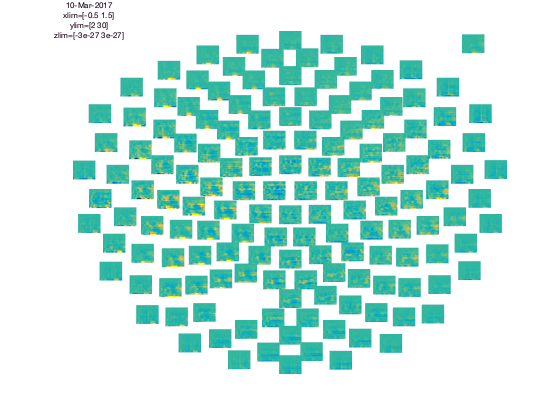

cfg = [];
cfg.baseline = [-0.5 -0.1];
cfg.zlim = [-3e-27 3e-27];
cfg.baselinetype = 'absolute';
cfg.layout = 'CTF151.lay';
figure; ft_multiplotTFR(cfg,TFRhann);

In the upper left corner you see the "COMMENT" element and in the upper right cornier you see the "SCALE" element. The scale contains the average of all channels.

The location of all channels and the COMMENT and SCALE placeholder can be visualized with


cfg = [];
cfg.layout = 'CTF151.lay';
cfg.layout = ft_prepare_layout(cfg);

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB


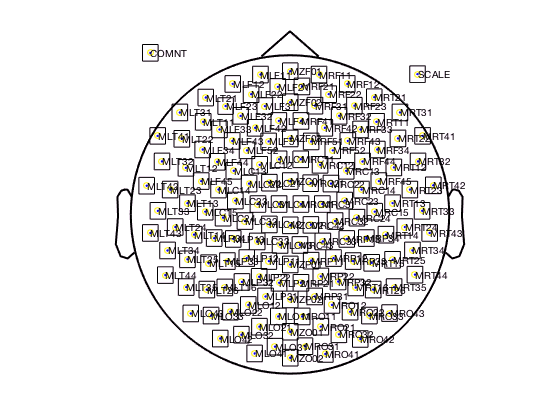

figure; ft_plot_lay(cfg.layout);

Note that the layout contains all 151 MEG channels; the one channel missing in the data is automatically excluded from the plots.

All channels are squeezed in a circle and the nose and ears are indicated at the top and sides. The actual 3-D layout of the MEG channels in the CTF system is more complex than the circular arrangement suggested by the flat 2-D layout. This is a generic challenge for projections onto a 2-D plane and also applies to cartography. We can plot the bottom coil of the CTF gradiometer channels with  

figure; 
ft_plot_sens(avgFC.grad, 'chantype', 'meggrad')
ft_plot_axes(avgFC.grad)

The axes are 15 cm long in each direction
The diameter of the sphere at the origin is 1 cm


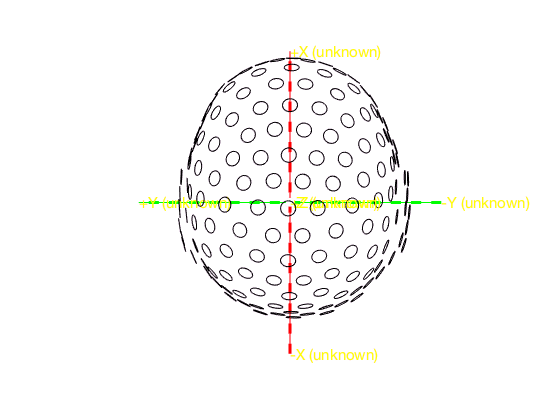

view(-90, 90) % you should rotate the figure to get a good 3-D feel of the channel locations. 

Although many tutorials elsewhere on the Fieldtrip wiki are using the standard CTF151 layout, we do have another one that better reflects the helmet shape:

cfg = [];
cfg.layout = 'CTF151_helmet.mat'; % note that it is a binary *.mat file, not an ascii *.lay file
cfg.layout = ft_prepare_layout(cfg);

reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 4 MB


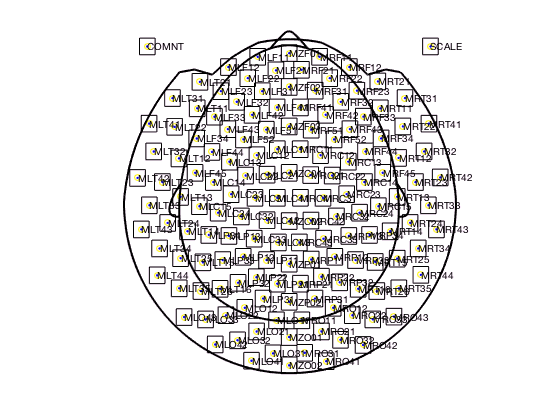

figure; ft_plot_lay(cfg.layout);

The layout is determined by the layout file. Read more on layout files [[tutorial:layout|here]], and in the [[faq:what_is_the_format_of_the_layout_file_which_is_used_for_plotting|frequently asked questions]].

For multiplotting planar gradient data from the Elekta Neuromag system it is especially relevant to understand the layout files. The Neuromag system has two planar gradiometers and one axial magnetometer at each sensor location. You do not want to plot those on top of each other. Hence the Neuromag layout files contain two (for the old 122 channel system) or three (for the recent 306 channel systems) seperate subplots for each channel location. Those two (or three) subplots hold the data for the two planar gradients and for the magnetometer signal.

cfg = [];
cfg.layout = 'neuromag306all.lay';
cfg.layout = ft_prepare_layout(cfg);

reading layout from file neuromag306all.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 7 MB


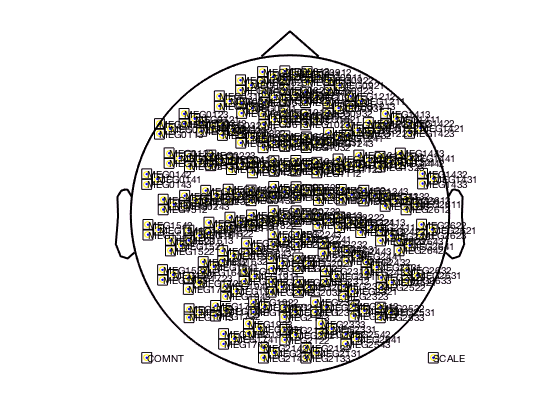

figure; ft_plot_lay(cfg.layout);

You should zoom in on the figure to see the triplets for the three channels ar each sensor locations. There are also template layouts available that only contain the magnetometer channels at the correct location (i.e. not shifted) and that contain the combined planar channels. The latter one can be used after applying ft_combineplanar on your data. 

**==== Topoplot functions ====**

Ft_topoplotER and ft_topoplotTFR plot the topographic distribution of 2-Dimensional or 3-Dimensional datatypes as a 2-D circular view (looking down at the top of the head). The arrangement of the channels is again specified in the layout (see above in multiplot functions). The ft_topoplotER and ft_topoplotTFR functions first again select the data to be plotted from the 2D or 3D input data and subsequently plot the selected data using low-level Fieldtrip functions. Using one value for each channel and the x and y coordinates, the values between points are interpolated and plotted. 

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
input data contains repetitions, ignoring these and using 'avg' field
the call to "ft_topoplotER" took 2 seconds and required the additional allocation of an estimated 14 MB


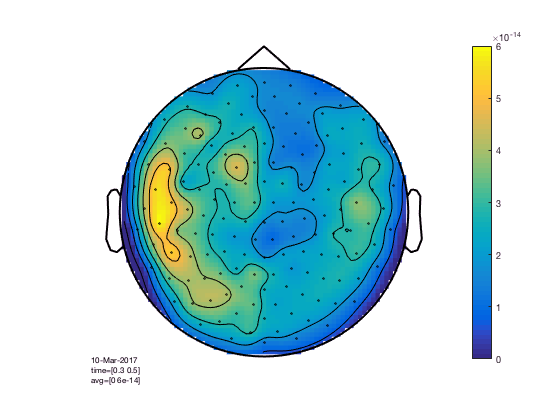

  cfg = [];                            
  cfg.xlim = [0.3 0.5];                
  cfg.zlim = [0 6e-14];                
  cfg.layout = 'CTF151.lay';            
  figure; ft_topoplotER(cfg,GA_FC); colorbar

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_topoplotTFR" took 2 seconds and required the additional allocation of an estimated 1 MB


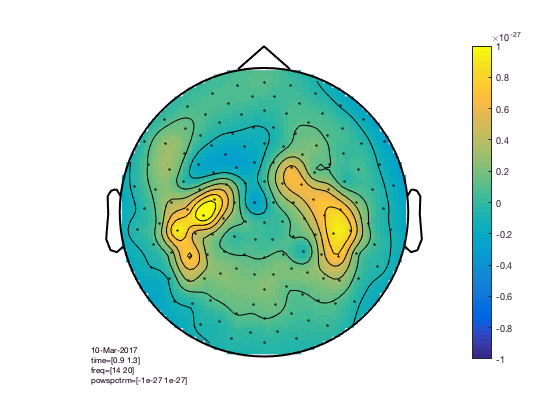

  cfg = [];
  cfg.xlim = [0.9 1.3];                
  cfg.ylim = [15 20];                  
  cfg.zlim = [-1e-27 1e-27];           
  cfg.baseline = [-0.5 -0.1];          
  cfg.baselinetype = 'absolute';
  cfg.layout = 'CTF151.lay';
  figure; ft_topoplotTFR(cfg,TFRhann); colorbar

You can compare this to the more realistic helmet-style layout, which better acknowledges the fact that the MEG channels extend below the ears and that the helmet has sort of an opening at the face.

layout file without .mat (or .lay) extension specified, appending .mat
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 2 seconds and required the additional allocation of an estimated 4 MB


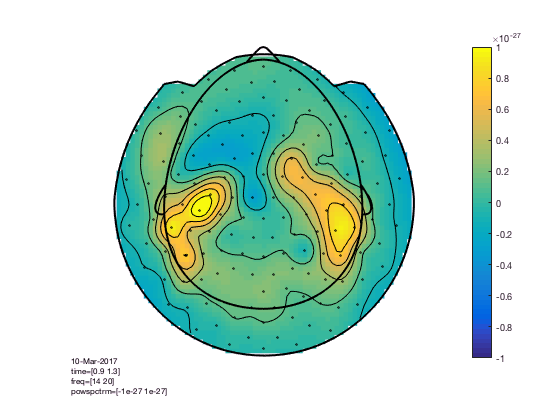

  cfg = [];
  cfg.xlim = [0.9 1.3];                
  cfg.ylim = [15 20];                  
  cfg.zlim = [-1e-27 1e-27]; % this is in T^2           
  cfg.baseline = [-0.5 -0.1];          
  cfg.baselinetype = 'absolute';
  cfg.layout = 'CTF151_helmet';
  figure; ft_topoplotTFR(cfg,TFRhann); colorbar

  The baseline correction computes the power difference compared to the pre-stimuls baseline. We can also look at the power ratio

layout file without .mat (or .lay) extension specified, appending .mat
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 2 seconds and required the additional allocation of an estimated 3 MB


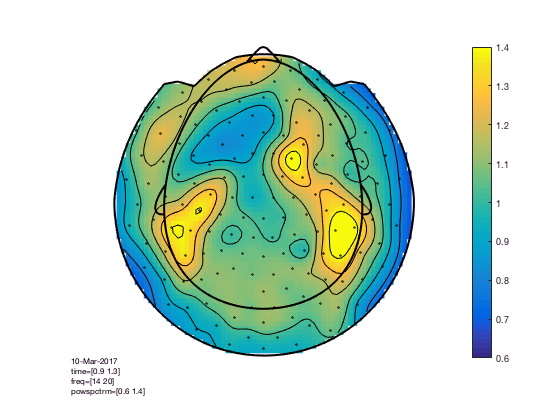

  cfg = [];
  cfg.xlim = [0.9 1.3];                
  cfg.ylim = [15 20];                  
  cfg.zlim = [0.6 1.4]; % the value 1 means 100%, so this ranges from 60% to 140% of the baseline power
  cfg.baseline = [-0.5 -0.1];          
  cfg.baselinetype = 'relative';
  cfg.layout = 'CTF151_helmet';
  figure; ft_topoplotTFR(cfg,TFRhann); colorbar

The interpretation becomes more clear with

  cfg = [];
  cfg.xlim = [0.9 1.3];                
  cfg.ylim = [15 20];                  
  cfg.zlim = [0.6 1.4]; % the value 1 means 100%, so this ranges from 60% to 140% of the baseline power
  cfg.baseline = [-0.5 -0.1];          
  cfg.baselinetype = 'relative';
  cfg.layout = 'CTF151_helmet';
  figure; ft_topoplotTFR(cfg,TFRhann); colorbar

layout file without .mat (or .lay) extension specified, appending .mat
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 2 seconds and required the additional allocation of an estimated 5 MB


  
  % so far it was the same as above, now change the colormap
  ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path

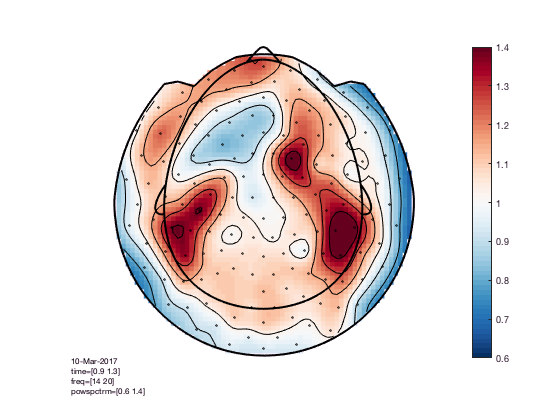

  colormap(flipud(brewermap(64,'RdBu'))) % change the colormap

See [http://colorbrewer2.org](http://colorbrewer2.org) for more details.

In the help of ft_topoplotER and ft_topoplotTFR you can find many cfg options. For instance by specifying the cfg.xlim as a vector the functions makes selections of multiple time-windows and plots them as a series of subplots.

reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 1 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 1 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_prepare_layout" took 0 seconds and required the addi

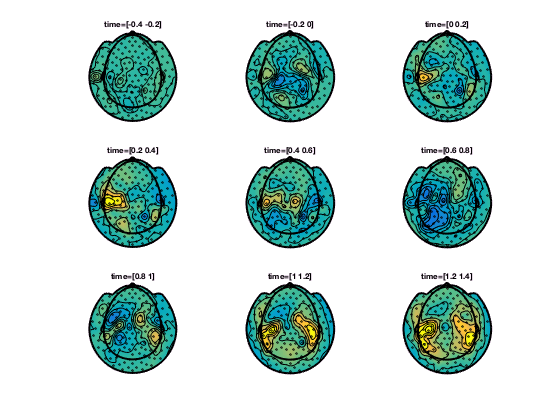

  % for the multiple plots also
  cfg = [];
  cfg.xlim = [-0.4:0.2:1.4];
  cfg.ylim = [15 20];                  
  cfg.zlim = [-1e-27 1e-27];            
  cfg.baseline = [-0.5 -0.1];          
  cfg.baselinetype = 'absolute';
  cfg.layout = 'CTF151_helmet.mat';
  cfg.comment = 'xlim';
  cfg.commentpos = 'title';
  figure; ft_topoplotTFR(cfg,TFRhann);

In ft_topoplotER and ft_topoplotTFR, you can specify many options to fully control the appearance of the picture. Subsequently you can use the MATLAB print function to write the figure to a file. Preferred file formats are EPS for vector drawings that can be edited in Adobe Illustrator or in Canvas (using “print -depsc”) or PNG for bitmaps (using “print -dpng”).

To make the EPS-files optimally suitable for Adobe Illustrator, use the command “print -depsc -adobecs -painter”. 

Since MATLAB uses the 'painter' renderer to export in Illustrator format, this method allows one to export quite complex figures that otherwise would be exported as bitmaps. Note, however, that the 'painter' renderer also has certain limitations compared to the z-buffer and openGL renderers. (See also MATLAB help on selecting a renderer).

Some examples of what you can do:

  % options for data selection (used with any plotting function):
  cfg = [];
  cfg.xlim = [0.9 1.3];
  cfg.ylim = [15 20];
  cfg.zlim = [-1e-27 1e-27];
  cfg.baseline = [-0.5 -0.1];
  cfg.baselinetype = 'absolute';
  cfg.layout = 'CTF151.lay';

Options specific to the topoplot

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 5 seconds and required the additional allocation of an estimated 8 MB


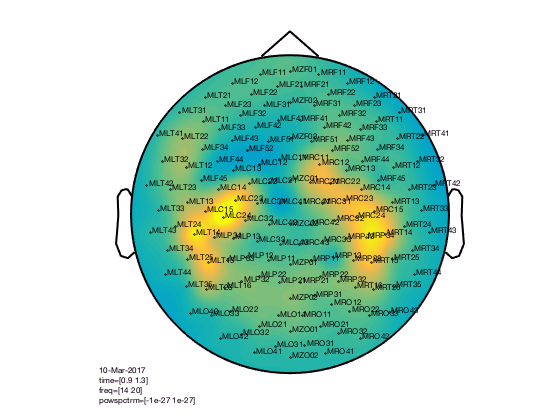

  cfg.gridscale = 300;                  
  cfg.style = 'straight';               
  cfg.marker = 'labels';                
  figure; ft_topoplotTFR(cfg,TFRhann);

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_topoplotTFR" took 2 seconds and required the additional allocation of an estimated 7 MB


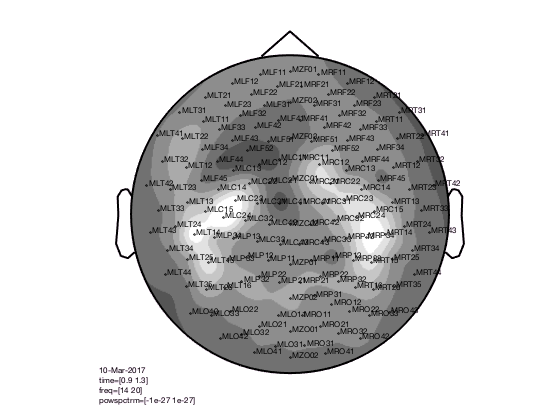

  cfg.gridscale = 300;                
  cfg.contournum = 10;                
  cfg.colormap = gray(10);            
  figure; ft_topoplotTFR(cfg,TFRhann);

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 4 seconds and required the additional allocation of an estimated 11 MB


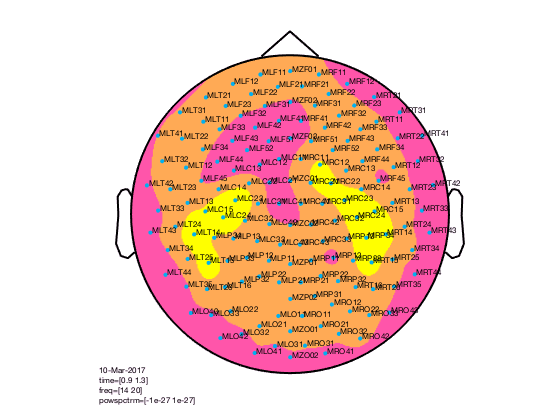

  cfg.gridscale = 300;
  cfg.contournum = 4;
  cfg.colormap = spring(4);
  cfg.markersymbol  = '.';
  cfg.markersize = 12;
  cfg.markercolor = [0 0.69 0.94];
  figure; ft_topoplotTFR(cfg,TFRhann);

**==== Interactive mode ====**

During the phase of the analysis in which you do a lot of data inspection, you can use the interactive modus to go from one plot to the other. You can for instance select a certain frequency and time range in a singleplot, to get the average over that range plotted in a topoplot. Or select a group of channels in a topoplot or a multiplot and get the average over those channels for the whole time and frequency range in a single plot.

reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_multiplotTFR" took 13 seconds and required the additional allocation of an estimated 5 MB


  %interactive
  cfg = [];
  cfg.baseline = [-0.5 -0.1];
  cfg.zlim = [-3e-27 3e-27];
  cfg.baselinetype = 'absolute';
  cfg.layout = 'CTF151.lay';
  cfg.interactive = 'yes';
  figure; ft_multiplotTFR(cfg,TFRhann);

You should select channels using the mouse and click, then you get singleplot average over those channels. You should select a time-frequency window and click, then you get topoplot average over that time-frequency window.

**==== Plotting clusters ====**

Ft_clusterplot plots a series of topoplots that highlight the clusters from cluster-based permutation testing. The output "stat" is 2D data from **[[reference:ft_timelockstatistics]]** or **[[reference:ft_freqstatistics]]** with cfg.correctm='cluster'. 

The function automatically finds the clusters in the data which are smaller than the pre-specified threshold (cfg.alpha) and plots a series of topoplots with the data in "stat" field (are for instance t-values) and the sensors which are part of the cluster highlighted. 

Stat should be 2D, i.e. channels-by-time, or channels-by frequency. You cannot visualize channels-by-frequency-by-time, that case requires either averaging over time, or averaging over frequency.

**== Clusters in timelocked data ==**

the input is timelock data with 149 channels and 76 timebins
reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
There are 2 clusters smaller than alpha (0.05)
Positive cluster: 1, pvalue: 0.009901 (*), t = 0.30667 to 0.82667
Negative cluster: 1, pvalue: 0.009901 (*), t = 0.37333 to 1
making subplot 1 from 53
making subplot 2 from 53
making subplot 3 from 53
making subplot 4 from 53
making subplot 5 from 53
making subplot 6 from 53
making subplot 7 from 53
making subplot 8 from 53
making subplot 9 from 53
making subplot 10 from 53
making subplot 11 from 53
making subplot 12 from 53
making subplot 13 from 53
making subplot 14 from 53
making subplot 15 from 53
making subplot 16 from 53
making subplot 17 from 53
making subplot 18 from 53
making subplot 19 from 53
making subplot 20 from 53
making subplot 21 from 53
making subplot 22 from 53
making subplot 23 from 53
making subplot 24 from 53
making s

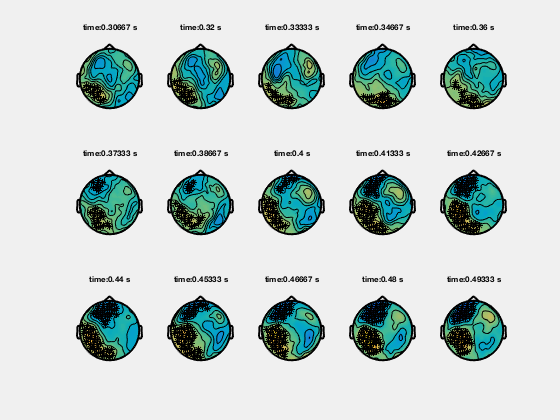

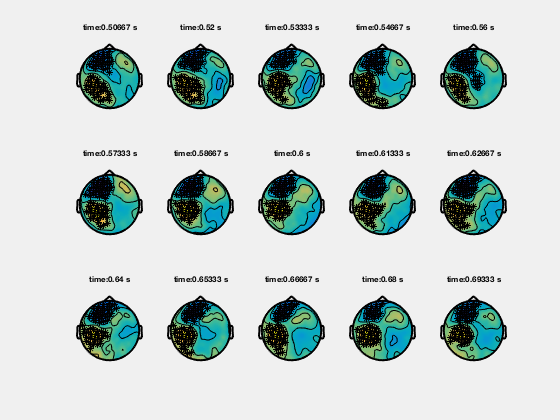

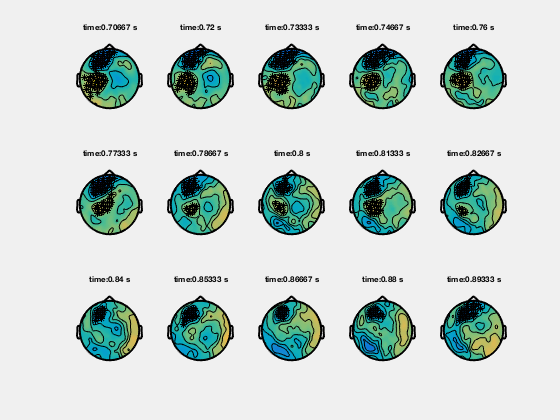

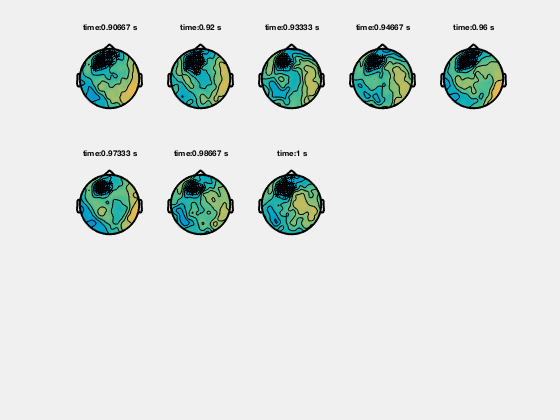

% clusterplot
cfg = [];
cfg.zlim = [-6 6]; % T-values
cfg.alpha = 0.05;
cfg.layout = 'CTF151.lay';
ft_clusterplot(cfg,statERF);

**== Clusters in time-frequency data ==**

the input is freq data with 149 channels, 1 frequencybins and 61 timebins
reading layout from file CTF151.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 11 MB
There are 1 clusters smaller than alpha (0.05)
Negative cluster: 1, pvalue: 0.003992 (*), t = 0.55 to 0.9
making subplot 1 from 8
making subplot 2 from 8
making subplot 3 from 8
making subplot 4 from 8
making subplot 5 from 8
making subplot 6 from 8
making subplot 7 from 8
making subplot 8 from 8
the call to "ft_clusterplot" took 28 seconds and required the additional allocation of an estimated 96 MB


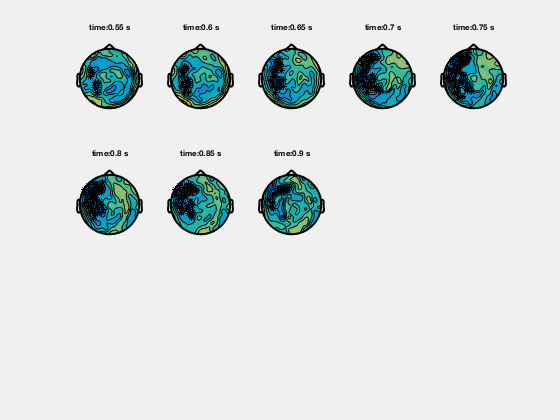

% clusterplot
cfg = [];
cfg.zlim = [-5 5];
cfg.alpha = 0.05;
cfg.layout = 'CTF151.lay';
ft_clusterplot(cfg,statTFR);

**==== Plotting channel-level connectivity ====**

This is possible using ft_connectivityplot,  ft_multiplotCC and ft_topoplotCC.

**==== Plotting Principal or Independent Components (PCA/ICA)====**

To plot PCA, ICA or other decompositions that result from ft_componentanalysis you can use ft_topoplotIC for the topographies and ft_databrowser for the topographies combined with the time series. For a viewer that displays the power spectrum, topography and variance over time of each component, see [[https://github.com/fieldtrip/fieldtrip/blob/master/contrib/misc/ft_icabrowser.m]].

**===== Plotting data at the source level =====**

With the ft_sourceplot function you can plot functional source reconstructed data. Data structures can be source estimates from ft_sourceanalysis or ft_sourcegrandaverage or statistical values from ft_sourcestatistics. The following sections will present the available options for source-level plotting, following the same structure as previous sections.

In visualising source reconstructed data, you should consider that  there are two principled ways of representing the spatial dimension of source reconstructed data: 

  - On a regular, 3-dimensional grid, i.e. volumetric data like an MRI scan 

  - On a surface geometry, i.e. a cortical sheet.

Besides the three dimensions that describe the spatial or geometrical aspect of source reconstructed brain activity, the data can have additional dimensions for time and/or frequency. 

**==== Volumetric data  ====**

Source level data is considered volumetric if the locations at which activity is estimated are spaced in a regular 3-dimensional grid, like voxels in an MRI. FieldTrip offers multiple plotting options for volumetric data that can be specified in the cfg for ft_sourceplot|ft_sourceplot.

You can (1) make multiple 2D axials slices throughout the brain on which the functional data is plotted, (2) create three slices in each of the three orthorgonal directions (axial, sagittal and coronal) on which you can click around to navigate the whole the brain (3) project the functional data onto a surface and make a 3-D rendering of that. 

Let us first provide the basic code to use one of these plotting methods, using the data from Subject01 from the beamformer tutorial.  Later on, we will give more details on the configuration options for ft_sourceplot.

**=== Individual anatomical MRI (prior to spatial normalization) ===**

% load MRI, reslice it and interpolate the low-res functional data onto the high-res anatomy
mri = ft_read_mri('Subject01.mri');  

mri = ft_volumereslice([], mri);

the input is volume data with dimensions [256 256 256]
reslicing from [256 256 256] to [256 256 256]
the input is volume data with dimensions [256 256 256]
the input is volume data with dimensions [256 256 256]
selecting subvolume of 90.4%
reslicing and interpolating anatomy
interpolating
interpolating 5.0%
interpolating 10.0%
interpolating 15.0%
interpolating 20.0%
interpolating 25.0%
interpolating 30.0%
interpolating 35.0%
interpolating 40.0%
interpolating 45.0%
interpolating 50.0%
interpolating 55.0%
interpolating 60.0%
interpolating 65.0%
interpolating 70.0%
interpolating 75.0%
interpolating 80.0%
interpolating 85.0%
interpolating 90.0%
interpolating 95.0%
interpolating 100.0%

the call to "ft_sourceinterpolate" took 11 seconds and required the additional allocation of an estimated 1896 MB
the call to "ft_volumereslice" took 12 seconds and required the additional allocation of an estimated 1928 MB



cfg            = [];
cfg.downsample = 2;
cfg.parameter  = 'pow';
sourceDiffInt  = ft_sourceinterpolate(cfg, sourceDiff , mri);

the input is volume data with dimensions [256 256 256]
the input is source data with 3042 brainordinates on a [18 13 13] grid


updating homogenous coordinate transformation matrix
downsampling anatomy
downsampling inside
the call to "ft_volumedownsample" took 0 seconds and required the additional allocation of an estimated 2 MB
selecting subvolume of 14.6%
interpolating
interpolating 95.0%

reslicing and interpolating pow
interpolating
interpolating 95.0%

the call to "ft_sourceinterpolate" took 4 seconds and required the additional allocation of an estimated 1173 MB


% spatially normalize the anatomy and functional data to MNI coordinates
cfg = [];
cfg.nonlinear = 'no';
sourceDiffIntNorm = ft_volumenormalise(cfg, sourceDiffInt);

the input is source data with 2097152 brainordinates on a [128 128 128] grid


Converting the coordinate system from ctf to spm


Rescaling NIFTI: slope = 0.00342945, intercept = 0
Smoothing by 0 & 8mm..
Coarse Affine Registration..


Fine Affine Registration..
performing the normalisation
warping the individual anatomy to the template anatomy, using only linear transformations
Smoothing by 0 & 8mm..
Coarse Affine Registration..
Fine Affine Registration..
creating normalised analyze-file for anatomy
creating normalised analyze-file for pow
creating normalised analyze-file for inside
the call to "ft_volumenormalise" took 22 seconds and required the additional allocation of an estimated 212 MB


the input is source data with 2097152 brainordinates on a [128 128 128] grid
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest
scaling anatomy
the call to "ft_sourceplot" took 2 seconds and required the additional allocation of an estimated 0 MB


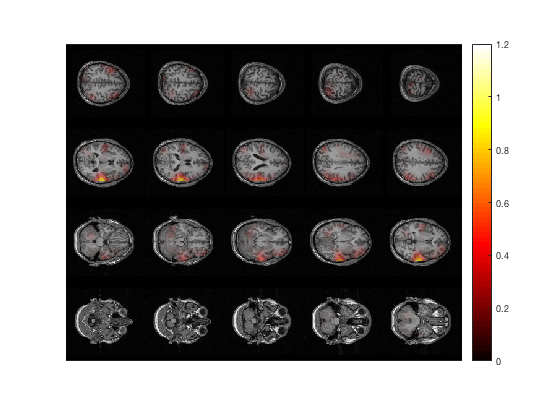

% plot multiple 2D axial slices
cfg = [];
cfg.method        = 'slice';
cfg.funparameter  = 'pow';
cfg.maskparameter = cfg.funparameter;
cfg.funcolorlim   = [0.0 1.2];
cfg.opacitylim    = [0.0 1.2]; 
cfg.opacitymap    = 'rampup';  
ft_sourceplot(cfg, sourceDiffInt);

the input is volume data with dimensions [181 217 181]
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest
scaling anatomy
the call to "ft_sourceplot" took 1 seconds and required the additional allocation of an estimated 190 MB


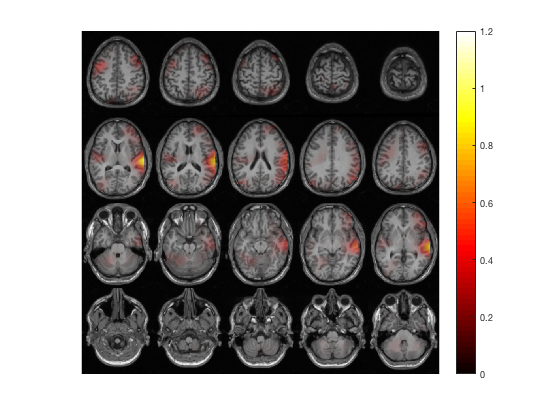


% idem, in MNI (or SPM) coordinates
ft_sourceplot(cfg, sourceDiffIntNorm);

the input is source data with 2097152 brainordinates on a [128 128 128] grid
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 3 seconds and required the additional allocation of an estimated 136 MB


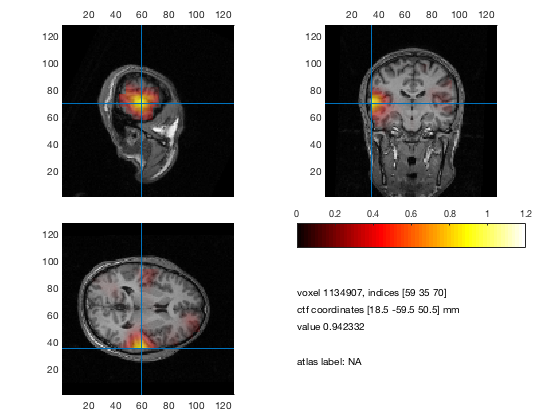

% plot 3 orthogonal slices
cfg = [];
cfg.method        = 'ortho';
cfg.funparameter  = 'pow';
cfg.maskparameter = cfg.funparameter;
cfg.funcolorlim   = [0.0 1.2];
cfg.opacitylim    = [0.0 1.2]; 
cfg.opacitymap    = 'rampup';  
ft_sourceplot(cfg, sourceDiffInt);

the input is volume data with dimensions [181 217 181]
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 2 seconds and required the additional allocation of an estimated 253 MB


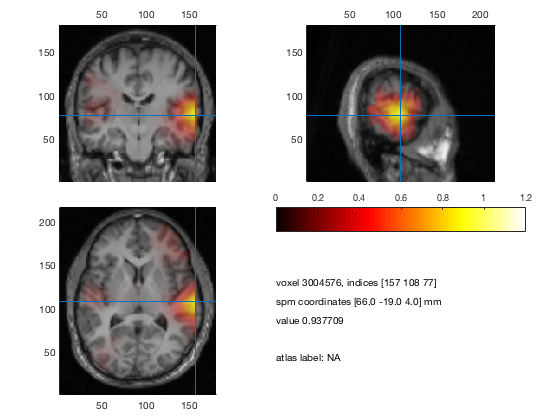


% idem, in MNI (or SPM) coordinates
ft_sourceplot(cfg, sourceDiffIntNorm);

The three essential cfg parameters are:

  * cfg.anaparameter the anatomy parameter, specifying the anatomy to be plotted

  * cfg.funparameter the functional parameter, specifying the functional data to be plotted

  * cfg.maskparameter the mask parameter, specifying the parameter to be used to mask the functional data

All data that is used in the figure (anatomical, functional, mask) must be interpolated and represented onto the same grid. See ft_sourceinterpolate and ft_volumenormalise.

**=== the anatomical parameter ===**

The anatomy can be read with **[[:reference:ft_read_mri]]**. The functional data can be interpolated onto the anatomy by **[[reference:ft_sourceinterpolate]]**. The anatomy is scaled between 0 and 1 and plotted in gray scale.

**=== the functional parameter ===**

The functional data is plotted in color optionally on top of the anatomy. The colors used can be determined by cfg.colormap (see MATLAB function COLORMAP). How the functional values are assigned to the colormap is determined by cfg.colorlim. It makes sense to plot for instance source data as functional parameter, but also statistical values (for instance T-values).

**=== the masking parameter ===**

You can control the opacity of the functional data by the mask parameter. Which values are plotted opaque and which transparent is determined by cfg.opacitymap and cfg.opacitylim (see MATLAB function ALPHA and ALPHAMAP). The opacity map determines the degree of opacity of the functional data going from opaque to transparent.  There are multiple ways to determine your opacity scale, as a user you can determine the opacity values for each and every single voxel (and as such, region of interest).  As such, the opacity limits determine how the opacity map is assigned to the values of the mask parameter.  

=== Example 1: Plotting only positive values ===

Imagine that your functional data has values ranging from -3 to 3. Here we plot only the positive values  (zeromax), using the scale whereby the strongest values are opaque, and the values close to zero are transparent:

`  cfg.maskparameter = cfg.funparameter`

`  cfg.colorlim      = [0 3] (or'zeromax')`

`  cfg.opacitymap    = 'rampup'`

`  cfg.opacitylim    = [0 3] (or 'zeromax')`

=== Example 2: Plotting high absolute values ===

Suppose the functional data is the same as in example 1, but now we only wants to plot the high negative values and high positive values (use "maxabs" setting). We set these high absolute values to opaque, and the values around zero to transparent:

`  cfg.maskparameter = cfg.funparameter`

`  cfg.colorlim      = [-3 3] (or'maxabs')`

`  cfg.opacitymap    = 'vdown'`

`  cfg.opacitylim    = [-3 3] (or'maxabs')`

=== Example 3: Masking voxels outside values of interest ===

Here, we make a field in the data with an opacity value for each voxel, and apply that as your mask. For instance if you only want to plot the values between 2 and 2.5 you can specify:

`  data.mask         = (data.fun>2 & data.fun<2.5)`

`  cfg.maskparameter = 'mask'`

==== Plotting on a brain surface ====

=== Scalar data per vertex ===

The representation of source activity on a surface results from source estimation using a cortical sheet as the source model. The cortical sheet is represented as a triangulated surface and the activity is assigned to each of the vertices, i.e. corner points of the triangles. Besides doing the source estimation on a cortical sheet, it is also possible to interpolate the volumetric data (i.e. estimated on a regular 3-D grid) onto a cortical sheet for visualization.

Scalar data (e.g., time-averaged activity, frequency-specific power estimates, statistics, etc.) can be plotted using the ft_plot_mesh function. Alternatively, volumetric data can also be rendered on a surface by projecting it to a surface geometry, using ft_sourceplot. An example of the latter is given below, where we use the same data as in the preceding section.

=== Project volumetric data to an MNI white-matter surface surface ===

cfg = [];
cfg.method         = 'surface';
cfg.funparameter   = 'pow';
cfg.maskparameter  = cfg.funparameter;
cfg.funcolorlim    = [0.0 1.2];
cfg.funcolormap    = 'jet';
cfg.opacitylim     = [0.0 1.2]; 
cfg.opacitymap     = 'rampup';  
cfg.projmethod     = 'nearest'; 
cfg.surffile       = 'surface_white_both.mat'; % Cortical sheet from canonical MNI brain
cfg.surfdownsample = 10;  % downsample to speed up processing
ft_sourceplot(cfg, sourceDiffIntNorm);

the input is volume data with dimensions [181 217 181]
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest
The source functional is defined on a 3D grid, interpolation to a surface mesh will be performed
the input is mesh data with 346499 vertices and 692990 triangles
downsampling surface from 346499 vertices
7109137 voxels in functional data
34653 vertices in cortical surface
the input is parcellated source data with 34653 vertex positions and 69298 triangles


the input is volume data with dimensions [181 217 181]
interpolating pow
interpolating pow
the call to "ft_sourceinterpolate" took 1 seconds and required the additional allocation of an estimated 193 MB
the call to "ft_sourceplot" took 13 seconds and required the additional allocation of an estimated 359 MB


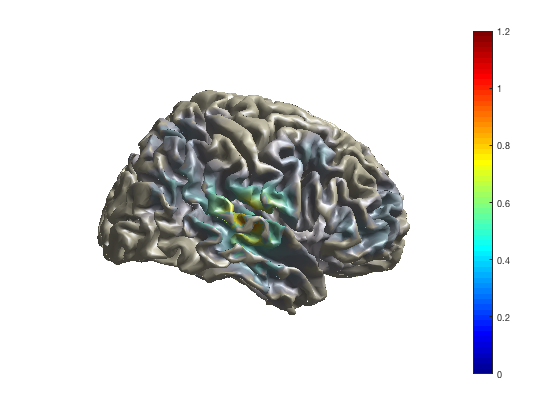


view ([90 0])             % rotate the object in the view

If you enable the camera toolbar (menu option "view", "camera toolbar") you have more options for controlling the 3-dimensional rendering, e.g. change perspective, change the position of the light (used for relection and shadows).

As with the channel-level multiplots, you can change the colormap that maps the functional values on the colors.

the input is volume data with dimensions [181 217 181]
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest
The source functional is defined on a 3D grid, interpolation to a surface mesh will be performed
the input is mesh data with 346499 vertices and 692990 triangles
downsampling surface from 346499 vertices
7109137 voxels in functional data
34653 vertices in cortical surface
the input is parcellated source data with 34653 vertex positions and 69298 triangles


the input is volume data with dimensions [181 217 181]
interpolating pow
interpolating pow
the call to "ft_sourceinterpolate" took 1 seconds and required the additional allocation of an estimated 191 MB
the call to "ft_sourceplot" took 12 seconds and required the additional allocation of an estimated 378 MB


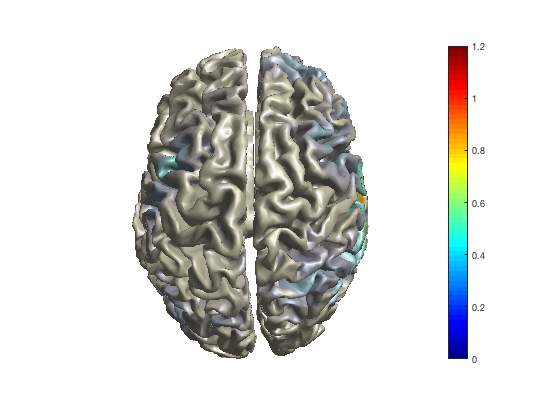

ft_sourceplot(cfg, sourceDiffIntNorm);

colormap jet

ft_sourceplot(cfg, sourceDiffIntNorm);

the input is volume data with dimensions [181 217 181]
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest
The source functional is defined on a 3D grid, interpolation to a surface mesh will be performed
the input is mesh data with 346499 vertices and 692990 triangles
downsampling surface from 346499 vertices
7109137 voxels in functional data
34653 vertices in cortical surface
the input is parcellated source data with 34653 vertex positions and 69298 triangles


the input is volume data with dimensions [181 217 181]
interpolating pow
interpolating pow
the call to "ft_sourceinterpolate" took 1 seconds and required the additional allocation of an estimated 191 MB
the call to "ft_sourceplot" took 12 seconds and required the additional allocation of an estimated 377 MB


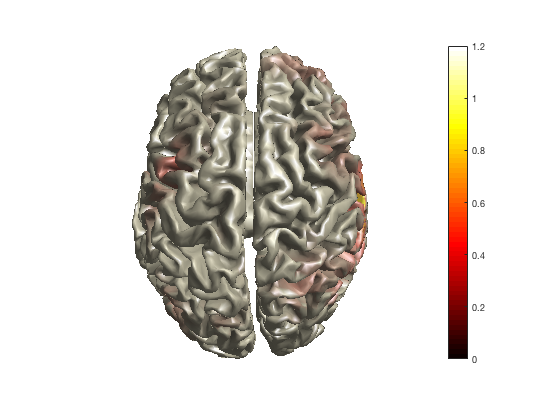

colormap hot


ft_sourceplot(cfg, sourceDiffIntNorm);

the input is volume data with dimensions [181 217 181]
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest
The source functional is defined on a 3D grid, interpolation to a surface mesh will be performed
the input is mesh data with 346499 vertices and 692990 triangles
downsampling surface from 346499 vertices
7109137 voxels in functional data
34653 vertices in cortical surface
the input is parcellated source data with 34653 vertex positions and 69298 triangles


the input is volume data with dimensions [181 217 181]
interpolating pow
interpolating pow
the call to "ft_sourceinterpolate" took 1 seconds and required the additional allocation of an estimated 191 MB
the call to "ft_sourceplot" took 15 seconds and required the additional allocation of an estimated 409 MB


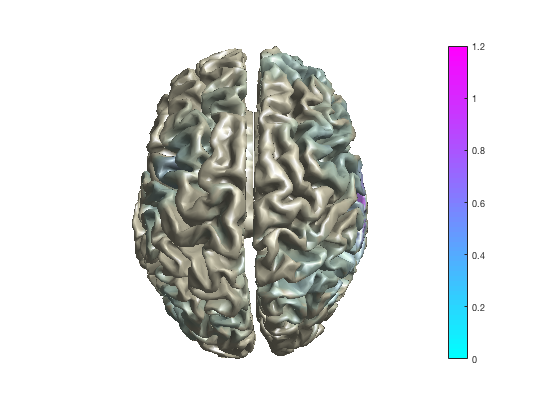

colormap cool

If you right-click with the mouse on the colobar in the figure, you can also also do this interactively.

To  interactively explore higher-dimensional data (such as TFR data) on the surface, ft_sourceplot cannot be used. You can make selections of a specific time and/or frequency and make a series of sublplots.

**=== Higher dimensional source-level data ===**

Since source-level function data requires three dimensions for "space" and uses the color dimension for "strength", there is no graphical dimension in which the temporal evolution or the spectral distribution can be visualized in full detail. The ft_sourceplot function allows you with method=ortho to use teh lower right corner of the figure to show the timecourse or spectrum of the functional activity at a specific location (the one you click). The ft_sourcemovie function allows you to use time (as in a movie) to explore the changes of cortical activity over time and/or frequency. 

**==== Using external tools ====**

Although MATLAB is a very flexible development and analysis environment, it is not super-fast in visualisation. Hence external visualisation tools are sometimes more useful for exploring your data. Volumetric and surface based data can be exported to standard file formats using **[[:reference:ft_sourcewrite]]**. Subsequently, you can use external tools such as

  * [[http://www.mccauslandcenter.sc.edu/mricro/mricron/index.html|MRIcron]]

  * [[http://www.openwalnut.org|OpenWallnut]]

  * [[http://www.humanconnectome.org/software/connectome-workbench.html|Connectome Workbench]]

  * https://github.com/piermorel/gramm

**=====Suggested further reading=====**

Plotting channel-level data in a 2-dimensional representation on your flat computer screen or on paper requires that the 3-dimensional channel positions are mapped or projected onto the 2-dimensional plane. The tutorial on [[layout|specifying the channel layout for plotting]] explains how this mapping is constructed.   